## 0. Initialize Parameters

n = 1251;                   % Number of locations to evaluate bridge failure
L = 1250;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
total_loads = zeros(1, n);  % Initialize total_loads for SFD(x)

## 1. Point Loading Analysis (SFD, BMD)

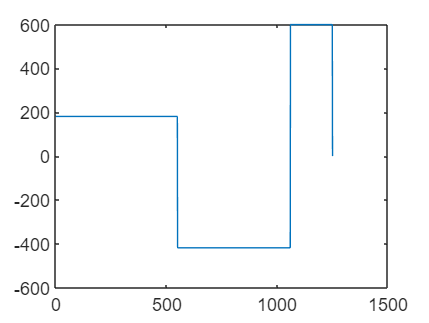

P = -600; % Change this variable
[SFD_PL, BMD_PL, total_loads] = ApplyPL(550, P, n, total_loads); % Construct load vector
[SFD_PL, BMD_PL, total_loads] = ApplyPL(L, P, n, total_loads); % Construct load vector
plot(x, SFD_PL)

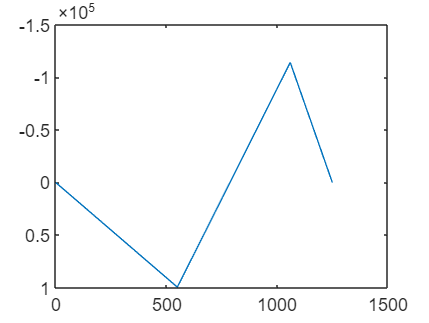

plot(x, BMD_PL)
set(gca, 'YDir', 'reverse')

## 1.1 Train Load

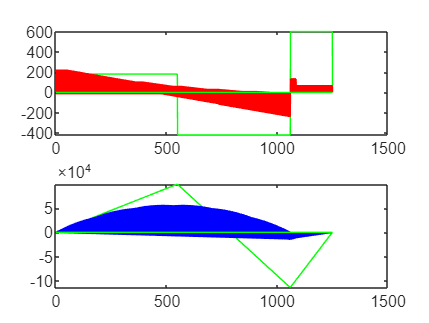

n = 1251;                   % Number of locations to evaluate bridge failure
L = 1250;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
total_loads = zeros(1, n);  % Initialize total_loads for SFD(x)
y_zero = zeros(1,n);        % Initialize y-axis

P = -400;
P_each = P/6;
for n = 52:1250
    x0=n;
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    for i=1:6
        if x_load(i)<=1250
            [SFD_TL, BMD_TL, total_loads] = ApplyPL(x_load(i), P_each, n, total_loads);
        end
    end
subplot(2,1,1);
plot(x, SFD_TL,'red')
plot(x, SFD_PL, 'green') % Plot point load SFD on same graph
hold on
subplot(2,1,2);
plot(x, BMD_TL,'blue')
plot(x, BMD_PL, 'green') % Plot point load BMD on same graph
% set(gca,'YDir','reverse')
hold on
SFD_PL = zeros(1,1251);
BMD_PL = zeros(1,1251);
total_loads = zeros(1,1251);
end

## 2. Define Cross-Sections

% Design0 
xc = [0 549 550 1059 1060 L]; % Location, x, of cross-section change
tfb = [100 100 100 100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27 1.27 1.27 1.27]; % Top Flange Thickness
wh = [72.46 72.46 72.46 72.46 72.46 72.46]; % Web Height
wt = [1.27 1.27 1.27 1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
ws = [80 80 80 80 80 80]; % Web Spacing
bfb = [80 80 80 80 80 80]; % Bottom Flange Width
bft = [1.27 1.27 1.27 1.27 1.27 1.27]; % Bottom Flange Thickness
gtb = [10 10 10 10 10 10]; % Glue Tab Width
gtt = [1.27 1.27 1.27 1.27 1.27 1.27]; % Glue Tab Thickness
a = [520 520 480 480 160 160]; % Diaphragm Spacing

tfb = interp1(xc, tfb, x);
tft = interp1(xc, tft, x);
wh = interp1(xc, wh, x);
wt = interp1(xc, wt, x);
ws = interp1(xc, ws, x);
bfb = interp1(xc, bfb, x);
bft = interp1(xc, bft, x);
gtb = interp1(xc, gtb, x);
gtt = interp1(xc, gtt, x);
a = interp1(xc, a, x)

a =    520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520   520


## 2.1 Calculate Cross-Sectional Properties

[ybot, ytop, I, Qcent, Qglue] = SectionProperties (x, n, tfb, tft, wh, wt, bfb, bft, gtb, gtt)

ybot =    41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016


ytop =    33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984


I = 	1.0e+05 *

    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569


Qcent = 	1.0e+03 *

    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484


Qglue = 	1.0e+03 *

    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483


[ybot_r, ytop_r, I_r, Qcent_r, Qglue_r] = SectionPropertiesRight (x, n, flh, flt, tfb_r, tft_r, wh_r, wt_r, bfb_r, bft_r, gtb_r, gtt_r)

Unrecognized function or variable 'SectionPropertiesRight'.

## 3. Define Material Properties

SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

## 4. Calculate Failure Moments and Shear Forces

M_MatT = MfailMatT( x, ybot, ytop, I, SigT, BMD_PL )
M_MatC = MfailMatC( x, ybot, ytop, I, SigC, BMD_PL )

bcent = 2 * wt
bglue = (2 * gtb) % + bcent % without bcent, assumes imperfect glue tab
[ V_MatFail, V_GlueFail ] = Vfail( Qcent, Qglue, bcent, bglue, I, TauU, TauG )

[ M_Buck1, M_Buck2, M_Buck3 ] = MfailBuck ( tft, tfb, wt, ws, bfb, bft, E, mu, I, ytop, ybot, BMD_PL )
V_Buck = VfailBuck ( x, wh, wt, a, E, mu, Qcent, bcent, I )

## 4.1 Calculate & Visualize Failure Loads

Pf = FailLoad(0, SFD_PL, BMD_PL, V_MatFail, V_GlueFail, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3)
VisualizePL(x, P, SFD_PL, BMD_PL, V_MatFail, V_GlueFail, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf);

## Function Definitions

function [ SFD_PL, BMD_PL, total_loads ] = ApplyPL( xP, P, n, total_loads )
% Constructs load vector from application of total point loads, then SFD & BMD from total loads.
% Assumes fixed location of supports.
% Input: location and magnitude of point load. The previous load vector can be entered as input to 
% construct the load vector of multiple point loads.
% Output: SFD_PL, BMD_PL, total_loads: 1-D arrays of length n
% xP = distance from left (A) support (x = 0)
xP_B = 1060;
cur_P_B = -P * xP / xP_B; % P_B due to current P
P_A = total_loads(1) -P - cur_P_B; % Overall P_A
P_B = cur_P_B + total_loads(xP_B+1); % Overall P_B

total_loads(1) = P_A;
total_loads(xP+1) = P;
if xP == xP_B
   total_loads(xP_B+1) = P_B + P;
else
    total_loads(xP_B+1) = P_B;
end

% Constructs SFD, BMD from all point loads applied.
SFD_PL = zeros(1, n);
SFD_PL(1) = total_loads(1);
    for i = 2:length(total_loads)
        SFD_PL(i) = total_loads(i) + SFD_PL(i-1);
    end
    BMD_PL = cumsum(SFD_PL);
end

function [ ybot, ytop, I, Qcent, Qglue ] = SectionProperties ( x, n, tfb, tft, wh, wt, bfb, bft, gtb, gtt )
% Calculates important sectional properties for left half . Including but not limited to ybar, I, Q, etc.
% Input: Geometric Inputs. Format will depend on user
% Output: Sectional Properties at every value of x. Each property is a 1-D array of length n

ovheight = tft + wh + bft; % Total height along beam

% Initialize A
tfa = zeros(1, n);
bfa = zeros(1, n);
wa = zeros(1, n);
gta = zeros(1, n);

% Initialize I_0
tfI = zeros(1, n);
bfI = zeros(1, n);
wI = zeros(1, n);
gtI = zeros(1, n);

tfIsum = zeros(1, n);
bfIsum = zeros(1, n);
wIsum = zeros(1, n);
gtIsum = zeros(1, n);

% Initialize ybar, I
ybot = zeros(1, n);
ytop = zeros(1, n);
I = zeros(1, n);

% Initialize Q sum value(s), Qcent, Qglue
wQ = zeros(1, n);
Qcent = zeros(1, n);
Qglue = zeros(1, n);

for i = 1:length(x)
    % Areas, A
    tfa(i) = tfb(i) * tft(i); % Assumes all values have been interpolated already
    bfa(i) = bfb(i) * bft(i); % If thickness remains constant, use # instead of vector
    wa(i) = 2 * wh(i) * wt(i); % Assumes 2 webs
    gta(i) = 2 * gtb(i) * gtt(i); % Assumes 2 glue tabs
    
    % Local centroids, y
    tfy = ovheight - (tft ./ 2);
    bfy = bft ./ 2;
    wy = (wh ./ 2) + bft;
    gty = ovheight(i) - tft(i) - (gtt ./ 2);

    % Global centroid, ybar
    ybot(i) = (tfa(i) * tfy(i) + bfa(i) * bfy(i) + wa(i) * wy(i) + gta(i) * gty(i)) / (tfa(i) + bfa(i) + wa(i) + gta(i));
    ytop(i) = abs(ybot(i) - ovheight(i));
    
    % I naught, I_0
    tfI(i) = (tfb(i) * (tft(i)^3)) / 12;
    bfI(i) = (bfb(i) * (bft(i)^3)) / 12;
    wI(i) = 2 * (wt(i) * (wh(i)^3)) / 12;
    gtI(i) = 2 * (gtb(i) * (gtt(i)^3)) / 12;

    tfIsum(i) = tfI(i) + tfa(i) * (abs(ybot(i) - tfy(i)))^2;
    bfIsum(i) = bfI(i) + bfa(i) * (abs(ybot(i) - bfy(i)))^2;
    wIsum(i) = wI(i) + wa(i) * (abs(ybot(i) - wy(i)))^2;
    gtIsum(i) = gtI(i) + gta(i) * (abs(ybot(i) - gty(i)))^2;

    % Second moment of area, I
    I(i) = tfIsum(i) + bfIsum(i) + wIsum(i) + gtIsum(i);

    % First moment of area, Q (Qcent & Qglue)
    wQ(i) = (2 * wt(i) * (ybot(i)-bft(i))) * ((ybot(i)-bft(i)) / 2);
    Qcent(i) = bfa(i) * (ybot(i)-(bft(i)/2)) + wQ(i);
    Qglue(i) = tfa(i) * (tfy(i) - ybot(i));
end
end

function [ V_MatFail, V_GlueFail ] = Vfail( Qcent, Qglue, bcent, bglue, I, TauU, TauG )
% Calculates shear forces at every value of x that would cause a matboard shear failure and a glue shear failure
% Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property)
% Output: V_MatFail, V_GlueFail, both 1-D arrays of length n
V_MatFail = zeros(1, length(Qcent));
V_GlueFail = zeros(1, length(Qglue));

for i = 1:length(Qcent)
    V_MatFail(i) = TauU * I(i) * bcent(i) / Qcent(i);
    V_GlueFail(i) = TauG * I(i) * bglue(i) / Qglue(i);

end
end

function [ V_Buck ] = VfailBuck ( x, wh, wt, a, E, mu, Qcent, bcent, I )
% Calculates shear forces at every value of x that would cause a shear buckling failure in the web
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property)
% Output: V_Buck a 1-D array of length n

SigCrit = zeros(1, length(x));
V_Buck = zeros(1, length(x));

for i = 1:length(x)
    SigCrit(i) = ((5 * pi^2 * E) / (12 * (1 - mu^2))) * (((wt(i) / wh(i))^2) + ((wt(i) / a(i))^2));
    V_Buck(i) = SigCrit(i) * I(i) * bcent(i) / Qcent(i);
end
end

function [ M_MatT ] = MfailMatT( x, ybot, ytop, I, SigT, BMD )
% Calculates bending moments at every value of x that would cause a matboard tension failure
% Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array)
% Output: M_MatT (1-D array of length n)
M_MatT = zeros(1, length(x));

for i = 1:length(x)
    if BMD(i) > 0 % If moment is (+), tension failure will be at the bottom
        M_MatT(i) = SigT * I(i) / ybot(i);
    elseif BMD(i) < 0 % If moment is (-), tension failure will be at the top
        M_MatT(i) = -SigT * I(i) / ytop(i);
    end
end
end

function [ M_MatC ] = MfailMatC( x, ybot, ytop, I, SigC, BMD )
% Calculates bending moments at every value of x that would cause a matboard compression failure
% Input: Sectional Properties (list of 1-D arrays), SigC (material property), BMD (1-D array)
% Output: M_MatT (1-D array of length n)
M_MatC = zeros(1, length(x));

for i = 1:length(x)
    if BMD(i) > 0 % If moment is (+), compression failure will be at the top
        M_MatC(i) = SigC * I(i) / ytop(i);
    elseif BMD(i) < 0 % If moment is (-), compression failure will be at the bottom
        M_MatC(i) = -SigC * I(i) / ybot(i);
    end
end
end

function [ M_Buck1, M_Buck2, M_Buck3 ] = MfailBuck ( tft, tfb, wt, ws, bfb, bft, E, mu, I, ytop, ybot, BMD )
% Calculates bending moments at every value of x that would cause a buckling failure
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array)
% Output: M_Buck1, M_Buck2, M_Buck3 (1-D array of length n)

% Case 1 (M_Buck1): Flange between webs, k = 4
% Case 2 (M_Buck2): Flange tips, k = 0.425
% Case 3 (M_Buck3): Webs, k = 6
n = 1251;
M_Buck1 = zeros(1, n);
M_Buck2 = zeros(1, n);
M_Buck3 = zeros(1, n);

% Top in Compression
Sig1top = zeros(1, n); % Sigma crit for Middle flange
Sig2top = zeros(1, n); % Flange tips
Sig3top = zeros(1, n); % Sigma crit for webs
b1top = ws - (2 * wt); % Middle flange width 
b2top = (tfb - ws) / 2; % Flange tip width
b3top = ytop - tft; % Web height (above ybar)

% Bottom in Compression
Sig1bot = zeros(1, n); % Sigma crit for Middle flange 
Sig2bot = zeros(1, n); % Flange tips
Sig3bot = zeros(1, n); % Sigma crit for webs
b1bot = ws - (2 * wt); % Middle flange width
b2bot = (bfb - ws) / 2; % Flange tip width
b3bot = ybot - bft; % Web height (below ybar)

for i = 1:n
    if BMD(i) > 0 % Top in Compression
        Sig1top(i) = ((4 * pi^2 * E) / (12 * (1 - mu^2))) * (tft(i) / b1top(i))^2;
        Sig2top(i) = ((0.425 * pi^2 * E) / (12 * (1 - mu^2))) * (tft(i) / b2top(i))^2;
        Sig3top(i) = ((6 * pi^2 * E) / (12 * (1 - mu^2))) * (wt(i) / b3top(i))^2;
        M_Buck1(i) = Sig1top(i) * I(i) / ytop(i);
        M_Buck2(i) = Sig2top(i) * I(i) / ytop(i);
        M_Buck3(i) = Sig3top(i) * I(i) / ytop(i);

    end

    if BMD(i) < 0 % Compression at bottom
        Sig1bot(i) = ((4 * pi^2 * E) / (12 * (1 - mu^2))) * (bft(i) / b1bot(i))^2;
        Sig2bot(i) = ((0.425 * pi^2 * E) / (12 * (1 - mu^2))) * (bft(i) / b2bot(i))^2;
        Sig3bot(i) = ((6 * pi^2 * E) / (12 * (1 - mu^2))) * (wt(i) / b3bot(i))^2;
        M_Buck1(i) = -Sig1bot(i) * I(i) / ybot(i);
        M_Buck2(i) = -Sig2bot(i) * I(i) / ybot(i);
        M_Buck3(i) = -Sig3bot(i) * I(i) / ybot(i);
    end  
end
end

function [ Pf ] = FailLoad( P, SFD, BMD, V_MatFail, V_GlueFail, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3 )
% Calculates the magnitude of the load P that will cause one of the failure mechanisms to occur
% Input: SFD, BMD under the currently applied points loads (P) (each 1-D array of length n)
% {V_Mat, V_Glue, … M_MatT, M_MatC, … } (each 1-D array of length n)
% Output: Failure Load value Pf
n = 1251;
P_local = -1;
total_loads = zeros(1, n);
[SFD_PL_local, BMD_PL_local, total_loads] = ApplyPL(550, P_local, n, total_loads);
[SFD_PL_local, BMD_PL_local, total_loads] = ApplyPL(1250, P_local, n, total_loads);
P_V_MatFail = min(abs(V_MatFail ./ SFD_PL_local))
P_V_GlueFail = min(abs(V_GlueFail ./ SFD_PL_local))
P_V_Buck = min(abs(V_Buck ./ SFD_PL_local))
P_M_MatT = min(abs(M_MatT ./ BMD_PL_local))
P_M_MatC = min(abs(M_MatC ./ BMD_PL_local))
P_M_Buck1 = min(abs(M_Buck1 ./ BMD_PL_local))
P_M_Buck2 = min(abs(M_Buck2 ./ BMD_PL_local))
P_M_Buck3 = min(abs(M_Buck3 ./ BMD_PL_local))
Pf = min([P_V_MatFail, P_V_GlueFail, P_V_Buck, P_M_MatT, P_M_MatC, P_M_Buck1, P_M_Buck2, P_M_Buck3]);
end

function [] = VisualizePL(x, P, SFD, BMD, V_MatFail, V_GlueFail, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf)
figure;

subplot(2, 3, 1)
hold on
title("SFD from P = -200N")
plot(x, SFD, 'k')
yline(0)
hold off

subplot(2, 3, [2,2,2])
hold on
title("SFD vs Material Shear Failures")
plot(x, V_MatFail)
plot(x, V_GlueFail)
plot(x, SFD, 'k')
yline(0)
legend('Matboard Shear', 'Glue Shear', '', 'Location', 'best')
hold off

subplot(2, 3, [3,3])
hold on
title("SFD vs Shear Buckling Failure")
plot(x, SFD, 'k')
plot(x, V_Buck)
yline(0)
legend('', 'Shear Buckling', 'Location', 'best')
hold off

subplot(2, 3, 4)
hold on
title("BMD from P = -200N")
plot(x, BMD, 'k')
yline(0)
hold off

subplot(2, 3, [5,5,5])
hold on
title("BMD vs Material Moment Failures")
plot(x, BMD, 'k')
plot(x, M_MatT)
plot(x, M_MatC)
yline(0)
legend('', 'Matboard Tension Failure', 'Matboard Compression Failure', 'Location', 'best')
hold off

subplot(2, 3, [6,6,6,6])
hold on
title("BMD vs Moment Buckling Failures")
plot(x, BMD, 'k')
plot(x, M_Buck1)
plot(x, M_Buck2)
plot(x, M_Buck3)
yline(0)
legend('', 'Mid Flange Buckling', 'Side Flange Buckling', 'Web Compression Buckling', 'Location', 'best')
hold off

end